open_system("Articulated_arm_homogeneous_combined_method");



test

path_simu = 'Articulated_arm_homogeneous_combined_method';

set_param(path_simu, 'SolverType', 'Fixed-step');   % fixed-step solver
%before : set_param(path_simu, 'FixedStep', '0.001');         % time step in sec
set_param(path_simu, 'FixedStep', '0.001'); 
%before set_param(path_simu, 'StopTime', '100'); 
set_param(path_simu, 'StopTime', '250');             % simulate time

Sweep Value

method_name = 'Basic Cost Function';
figure; hold on; grid on;
colors = {'b','r'};

K1 = 0.08;
K2 = 0.4;
K3 = 0.4;
delta_theta_vals = [0.5, 2];

epsilon = 0.01;

L1 = 0.2;
L2 = 0.2;
L3 = 0.2;


x_target = -0.2;
y_target = 0.35;


set_param(path_simu, 'FastRestart', 'off');

for i4 = 1:numel(delta_theta_vals)
    set_param([path_simu '/Gain3'],  'Gain', num2str(K1));
    set_param([path_simu '/Gain9'],  'Gain', num2str(K1));
    set_param([path_simu '/Gain4'],  'Gain', num2str(K2));
    set_param([path_simu '/Gain10'], 'Gain', num2str(K2));
    set_param([path_simu '/Gain5'],  'Gain', num2str(K3));
    set_param([path_simu '/Gain8'],  'Gain', num2str(K3));
    set_param([path_simu '/delta_angle_deg_const'], 'Value', num2str(delta_theta_vals(i4)));

    %Test
    get_param([path_simu '/delta_angle_deg_const'], 'Value')
    get_param([path_simu '/Gain3'], 'Gain')
    get_param([path_simu '/Gain4'], 'Gain')
    get_param([path_simu '/Gain5'], 'Gain')

    simOut = sim(path_simu);
    
    %Test
    disp(simOut.SimulationMetadata.ExecutionInfo.StopEvent);

    logsout = simOut.logsout;

    t = logsout.getElement('theta_1').Values.Time;

    theta_1_signal = logsout.getElement('theta_1');
    theta_2_signal = logsout.getElement('theta_2');
    theta_3_signal = logsout.getElement('theta_3');

    theta_1_array_prev = squeeze(theta_1_signal.Values.Data);
    theta_2_array_prev = squeeze(theta_2_signal.Values.Data);
    theta_3_array_prev = squeeze(theta_3_signal.Values.Data);

    theta_1_array = theta_1_array_prev(:,1);
    theta_2_array = theta_2_array_prev(:,1);
    theta_3_array = theta_3_array_prev(:,1);
    
    %Test
    disp([min(theta_1_array) max(theta_1_array)]);

    x = L1*cos(theta_1_array+pi/2) + L2*cos(theta_1_array+theta_2_array+pi/2) + L3*cos(theta_1_array+theta_2_array+theta_3_array+pi/2);
    y = L1*sin(theta_1_array+pi/2) + L2*sin(theta_1_array+theta_2_array+pi/2) + L3*sin(theta_1_array+theta_2_array+theta_3_array+pi/2);
    
    dist = sqrt((x - x_target).^2 + (y - y_target).^2);

    plot(t, dist, colors{i4}, 'LineWidth', 1.5, 'DisplayName', sprintf('delta\\_theta = %.2f', delta_theta_vals(i4)));
end

ans = '0.5'

ans = '0.08'

ans = '0.4'

ans = '0.4'

-------------------------
end = -0.220718
end = 0.000000
end = 0.169459
-------------------------
best_next_theta_1_pos = 0.000000
best_next_theta_2_pos = 0.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 1.000000
best_next_theta_2_neg = 1.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.218128
end = 0.000000
end = 0.172763
-------------------------
best_next_theta_1_pos = 0.000000
best_next_theta_2_pos = 0.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 1.000000
best_next_theta_2_neg = 1.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.215352
end = 0.000000
end = 0.176077
-------------------------
best_next_theta_1_pos = 0.000000
best_next_theta_2_pos = 0.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 1.000000
best_next_theta_2_neg = 1.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.212067
end = 0.000000
end = 0.179763
-------------------------
best_next_thet

ReachedStopTime


    1.2087    1.4021



ans = '2'

ans = '0.08'

ans = '0.4'

ans = '0.4'

-------------------------
end = -0.220718
end = 0.000000
end = 0.169459
-------------------------
best_next_theta_1_pos = 0.000000
best_next_theta_2_pos = 0.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 1.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.221645
end = 0.000000
end = 0.172172
-------------------------
best_next_theta_1_pos = 0.000000
best_next_theta_2_pos = 0.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 1.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.221691
end = 0.000000
end = 0.172324
-------------------------
best_next_theta_1_pos = 0.000000
best_next_theta_2_pos = 0.000000
best_next_theta_3_pos = 1.000000
best_next_theta_1_neg = 1.000000
best_next_theta_2_neg = 0.000000
best_next_theta_3_neg = 0.000000
-------------------------
end = -0.222682
end = 0.000000
end = 0.175458
-------------------------
best_next_thet

ReachedStopTime


    1.1678    1.3965



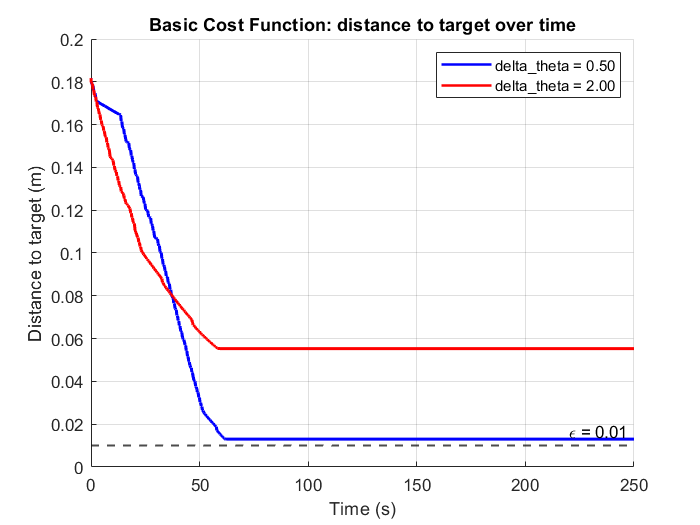


yline(epsilon, 'k--', '\epsilon = 0.01', 'LineWidth', 1.2, 'HandleVisibility','off');
xlabel('Time (s)');
ylabel('Distance to target (m)');
title([method_name ': distance to target over time']);
legend('Location','northeast');

fname = [matlab.lang.makeValidName(method_name) '_convergence.png'];
exportgraphics(gcf, fname, 'Resolution', 300);

disp(['Saved: ' fname]);

Saved: BasicCostFunction_convergence.png
